# Module 1 Video 2

## Batch Processing with Image Data Store

imageFolder = fullfile(toolboxdir("nnet"), "nndemos", "nndatasets", "DigitDataset");

imds = imageDatastore(imageFolder, "IncludeSubfolders", true, "LabelSource", "foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\MATLAB\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadF

Image = [];
Label = [];
Angle = [];

while hasdata(imds)
    [img, imgInfo] = read(imds);
    
    imgBW = imbinarize(img);
    props = regionprops("table", imgBW, "Orientation");
    
    
    if height(props) == 1
        Image = [Image; string(imgInfo.Filename)];
        Label = [Label; imgInfo.Label];
        Angle = [Angle; props.Orientation];
    end
end

digitData = table(Image, Label, Angle)

digitData = 8954×3 table
                                                Image                                                 Label     Angle 
    ______________________________________________________________________________________________    _____    _______

    "C:\Program Files\MATLAB\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png"      0       6.7263
    "C:\Program Files\MATLAB\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png"       0       82.052
    "C:\Program Files\MATLAB\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png"       0      -44.263
    "C:\Program Files\MATLAB\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9003.png"       0       78.965
    "C:\Program Files\MATLAB\R2024a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9004.png"       0       70.774
    "C:\Program Files\MATLAB\R2024a\too

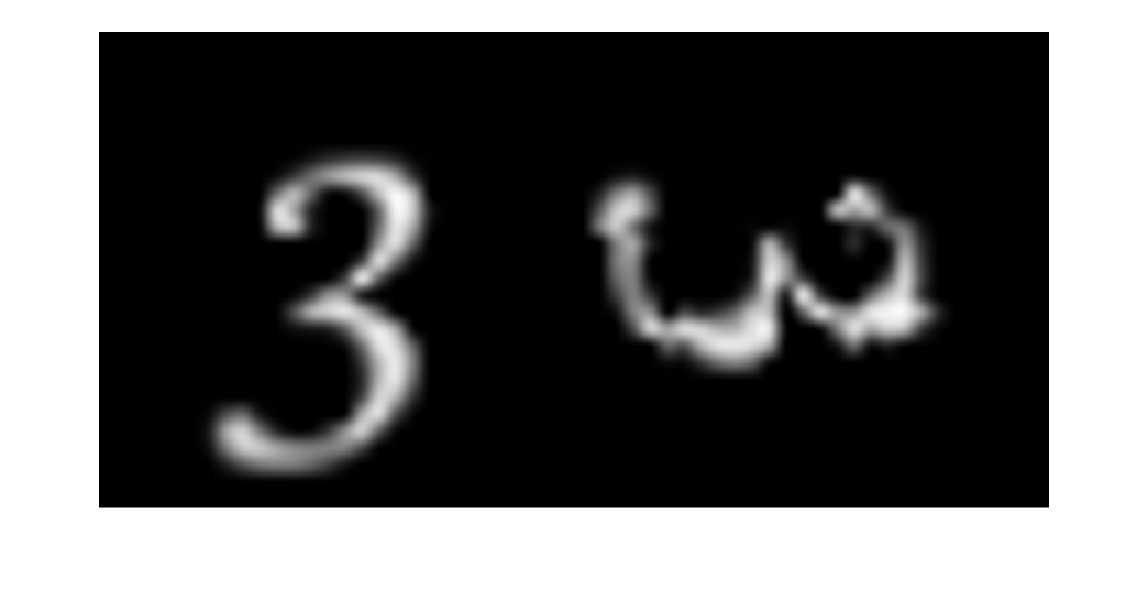

indx = 3333;
img = readimage(imds, indx);
Ang = table2array(digitData(indx, 3));
imgRotated = imrotate(img, Ang, "crop");
montage({img, imgRotated})